# Testing Pipeline 01.04.00

clear;
close;
clc;

%current path is always the folder storing the data folders or groups. 
%   C:\Users\Vini\MATLAB Drive\John Studies Drive\analysis  

## Get access to your current path

- **cd** => current directory 

- **dir** => lists files inside a folder

- we call our folders: groups

-     groups can be various settings or different circumstances of a recording, which later to be compared

%groupsRaw contains files and folders that are not part of our structure
groupsRaw = dir(cd); %get access to all files within the currentpath 

## Blacklists files that should not be shown inside groups

- can be anything, i.e. standard files like '.', '..', 'MATLABDriveTag' those are created by default and must be hidden

- . %first {} is the field where to change stuff, 2nd {} are the blacklisted words

- ~ismember as logical array to only return values that are 1 into groups

- i.e. '.','..','.MATLABDriveTag' are members of groupsRaw.name. but logically inverted "~" to strike them out of the groupsRaw.name field. ==> ***only important folders are left***

%get rid of blacklisted words and save the needed ones into the correct
%struct
groups_struct = groupsRaw(~ismember({groupsRaw.name},{'.', '..','.MATLABDriveTag'...
,'colorarea.mlx'...
,'find_intervals.mlx'...
,'find_riseToFall.mlx'...
,'function'...
,'getContactSwitch.mlx'...
,'getNormalizedGait.mlx'...
,'getPathProperties.mlx'...
,'getPathProperties_2.mlx'...
,'getSignalString.mlx'...
,'getSourceContacts.mlx'...
,'getSourceSignals.mlx'...
,'normalizeAndPlot.mlx'...
,'setSubStructs.mlx'...
,'getRecords.mlx'...
,'getGroupName.mlx'...
,'replaceFirstFourHyphens.mlx'...
,'normalizeContactsMergePlots.mlx'...
,'setSubChild.mlx'}));

## GROUPS

%store group member inside a cell array
groups = {groups_struct.name}';
clear groups_struct groupsRaw

## Set the used folders as your group structs 

- create a root struct.

- fill as many fields inside the root struct, as you see groups inside your groups cell array.

- eventually initialize them as structs as well.

- at last ***fetch your records*** as described below.

get access to .mat files inside the different groups using dir again this time with ****/*** accessing every single folder inside analysis (root)

- also store different fileNames inside a new cellArray called records, together with their group 

- fileNames is a combination of temp.name and temp.folder

- matlab acts weirldy when confronted with "-" instead of "_" so we have to change that as well  

## RECORDS

temp = dir('**/*.mat');
analysis = setSubStructs(groups,true); %root

%lines 36-42 seem redundant
tempCell = cell(1,length(struct2table(temp).folder));
for i = 1:length(tempCell)
    tempCell{i} = append(struct2table(temp(i)).folder,"\",(temp(i).name));
end
%tempCell contains every records path
tempCell = tempCell';
clear i;

% records col 1:    contains group information  
% records col 2:    contains full path information
% records col 3:    contains record name information 
records = getPathProperties_2(tempCell,groups);
for i = 1:length(tempCell)
    records{i,2} = tempCell{i};
    records{i,3} = temp(i).name;
end
clear i temp tempCell;

## Biomechanic dictionary 

%mapValues = [1 2 3];
joint_names = ["Knee", "Hip", "Ankle"];
sides =["RT", "LT"];
movementTypes = ["Flexion","Flexion","Dorsiflexion"];
contact_types = ["RT-Contact", "LT-Contact"];
intervals = [];

%update version for dictionary
%d = dictionary(joint_names,mapValues)

record_Count = length(records);
joint_names_Count = length(joint_names);
side_Count = length(sides);
group_Count = length(groups);
movementTypes_Count = length(movementTypes);
recordsTable = cell2table(records,"VariableNames",["group" "path" "record_name"]);

## Expand group structs

goal is to use *Biomechanic dictionary,* such that for each *side(s) *is extended by *joint_name(s) *each and each *joint_name(s) *is extended by each *movementType(s)*

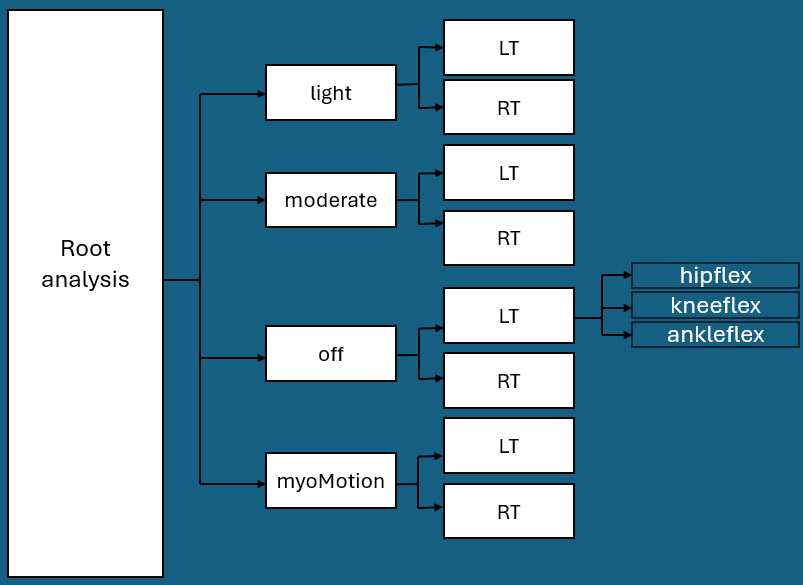

% distinctGroups = strrep(unique(recordsTable.group),"\","");




for group_index = 1:group_Count
    for joint_index = 1:joint_names_Count
        for side_index = 1:side_Count
            for movementType_index = 1:movementTypes_Count
                 analysis.(groups{group_index}).(sides(side_index)).(append((joint_names(joint_index)),(movementTypes(movementType_index)))) = struct();
            end
        end
    end
end

for record_index = 1:record_Count
    rec = load(records{record_index,2}); %load the current record
    recName = string(fieldnames(rec));  %get the records name as string
    myoMotionFlag = (records{record_index,1} == "\myomotion\"); %boolean to compare group to myomotion 
    
    % sourceName_Contact = getSourceSignals(rec,"",4); %"" paranthesis should be a vector which loops through every stringSet
    sourceName_Joint = getSourceSignals(rec,"",4);
    
    % signaleName_Contact = getSignalString(rec.(recName).movements.sources(4).signals,"editHere_contact");
    signalName_Joint = getSignalString(rec.(recName).movements.sources(4).signals,"editHere_");
    
    intervals = find_intervals(rec.(recName).movements.sources(4).signals.("editHere"));
    
    
    %check wheter we want to fetch IMU-Data or MP Data
    if myoMotionFlag 
        %fetch IMU-Data here if record in line has the groupName
        %\myomotion\ 
        disp("myoFlagged");
        disp(records{record_index,1})

        %fetch the imu sourceName and signal Name        
        sourceName_Joint = getSourceSignals(rec,"",4); %source Struct as a result
        signalName_Joint = getSignalString(rec.(recName).movements.sources(4).signals,"editHere_");
        
        normalizedRec = getNormalizedGait(rec.(recName {1,1}).movements)
        analysis = setRecordsIntoStruct
    else
        %fetch mp engine data here
        disp(records{record_index,1});
    end

end

Index exceeds the number of array elements. Index must not exceed 0.

Error in getSignalString (line 7)
        signalName = strcat("signal_",Signalstring(i));